clc
clear 
close

run('BASIC.m')

sys_discret =
 
  0.0076672 (z-0.7239) (z-0.8621)
  -------------------------------
  (z-1.109) (z-0.6048) (z-0.5835)
 
Sample time: 0.094282 seconds
Discrete-time zero/pole/gain model.




Titlework='Q11'

Titlework = 'Q11'

## Desigered System

%run('am.mlx');
%A_m=den_discret_desierd%A=den_discret
A_m=poly([0.80 0.65 0.69]);


betaa=sum(A_m)/sum(B);
B_m=B*betaa;
B_plus=1;

## MDPP with no zero canselation

A_o=[1 0 0];
A_c=conv(A_m,A_o)

A_c =     1.0000   -2.1400    1.5205   -0.3588         0         0


[R_prim , S] = Diophantine(A , B , A_c)

R_prim =     1.0000   -2.3862    1.2188


S =   331.7730 -367.4603   99.7126


T=conv(betaa,A_o)

T =    74.3410         0         0


R=conv(R_prim,B_plus)

R =     1.0000   -2.3862    1.2188


tfinal=200;

t = 0:T_s:tfinal;
uc=gensig('square' , tfinal/3 , tfinal ,T_s);

u=zeros(numel(t),1);
y=zeros(numel(t),1);

for i=10:numel(t)
    var1=conv(B,T)  ;       narv1=numel(var1)      ;
    var2=A_c(2:end) ;       narv2=numel(A_c(2:end));
    var3=conv(A,T)  ;       narv3=numel(var3)      ;

    y(i)=var1*uc(i:-1:i-narv1+1)-var2*uc(i-1:-1:i-narv2);
    u(i)=var3*uc(i:-1:i-narv3+1)-var2*uc(i-1:-1:i-narv2);
end


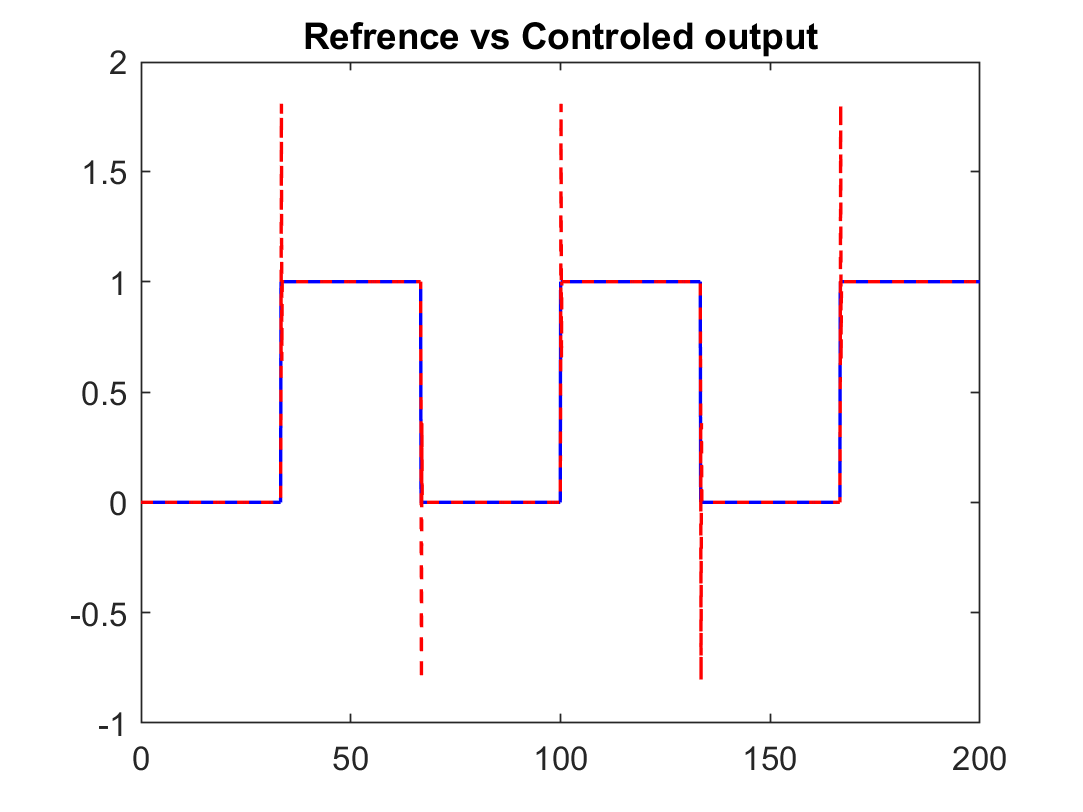

plot(t,uc,'b',t,y,'r--','LineWidth',1)
title('Refrence vs Controled output')
print(gcf,[Titlework ' Refrence vs Controled output.png'],'-dpng','-r400');

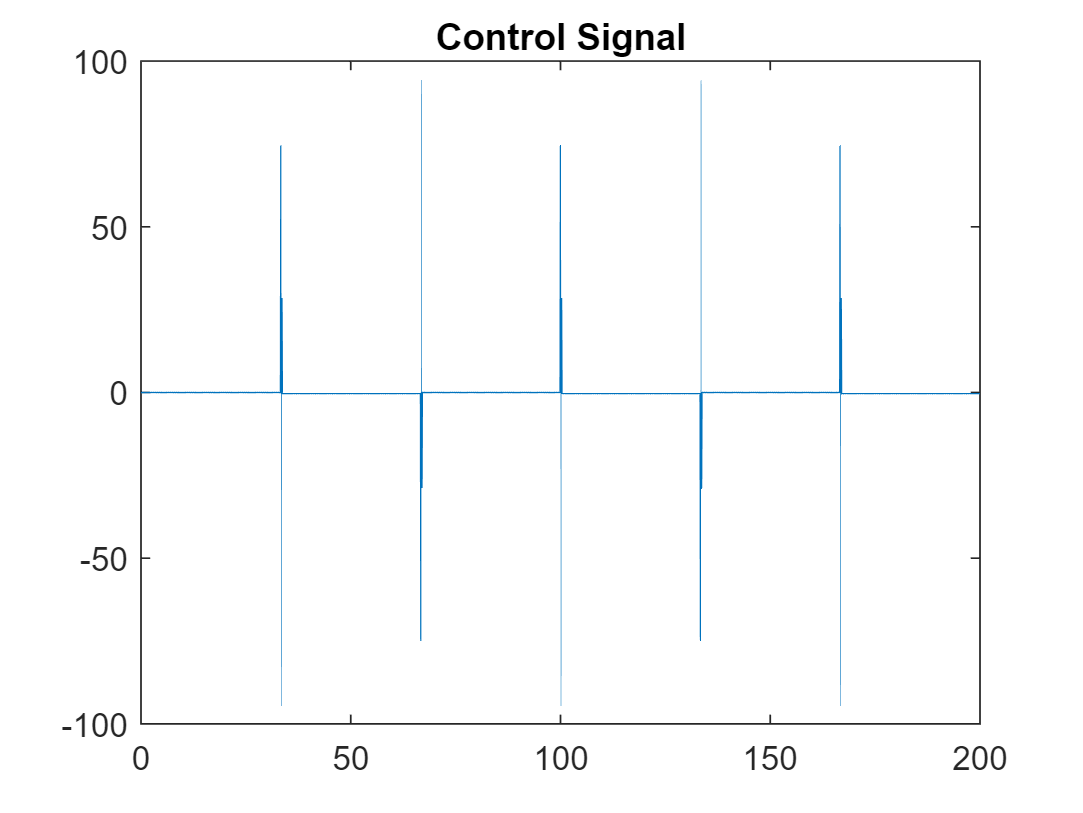


plot(t,u)
title('Control Signal')
print(gcf,[Titlework ' Control Signal.png'],'-dpng','-r400');